*This program is used for the course "Spaceflight Mechanics" at FH Aachen University of Applied Sciences*

*Version 21.0 by Bernd Dachwald – 20 Nov 2021*

clear

**User Input**

alpha = 90.0; % thrust angle in [°]
m0 = 1000.0; % initial spacecraft mass in [kg]
thrust = 1.0; % thrust in [N]
Isp = 4000; % specific impulse in [s]
tmax = 60.0; % integration time in [d]

**General Constants for the Problem**

mu = 398600.4*1e9; % gravitational parameter of the Earth in [m^3/s^2]
R = 6378.14*1e3; % Earth radius in [m]
g0 = 9.80665; % Earth standard gravitational acceleration in [m/s^2]

**Convert Input to "Correct" Units**

alpha = alpha*pi/180; % thrust angle in [rad]
ceff = Isp*g0; % effective exhaust velocity in [s]
tmax = tmax*86400; % max integration time in [s]
tint = 0:tmax/10000:tmax; % integration time span in [s]

**Initial Values**

h0 = 200.0*1e3; % initial altitude in [m]
r0 = R+h0; % initial orbit radius in [m]
phi0 = 0.0; % initial orbit angle [rad]
rho_r0 = 0.0; % initial radial velocity in [m/s]
v0 = sqrt(mu/r0); % initial orbital velocity in [m/s]
rho_phi0 = v0/r0; % initial orbital angular velocity in [rad/s]

**Solve Differential Equation System (DES)**

Opt = odeset('Events',@myEvent);
f = @(t,x) [
    x(3);
    x(4);
    x(1)*(x(4))^2-mu/(x(1))^2+thrust*cos(alpha)/x(5);
    1/x(1)*(thrust*sin(alpha)/(x(5))-2*x(3)*x(4));
    -thrust/ceff
    ];
[t,sc] = ode113(f,tint,[r0 phi0 rho_r0 rho_phi0 m0],Opt);

**Plot Solution**

Extraxt Values from DES Solution

r = sc(:,1)/1000;
phi = sc(:,2);
x = r.*cos(phi);
y = r.*sin(phi);
m = sc(:,5);

Plot

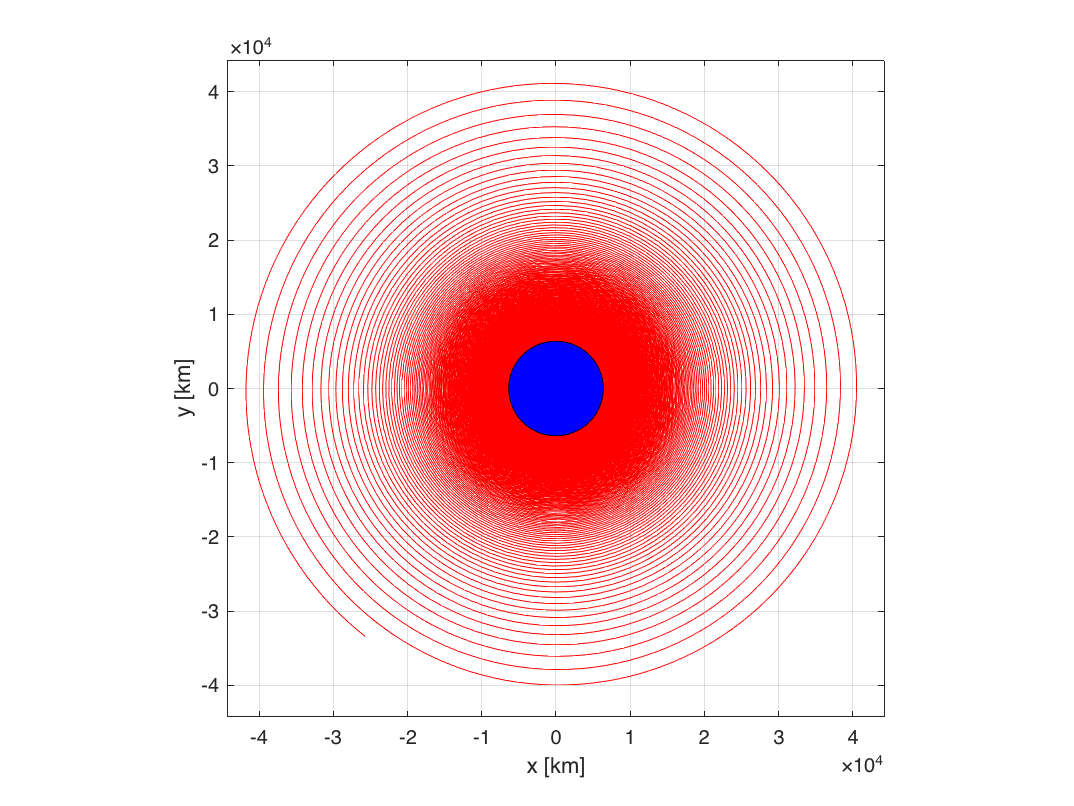

plotdim = 1.05*max(r); % plot dimension
earthdim = 2*R/1000; % Earth diameter in plot
xlim([-plotdim plotdim]) % x-axis dimension
ylim([-plotdim plotdim]) % y-axis dimension
pbaspect([1 1 1]) % aspect ration (makes plot quadratic)
hold on
box on % makes box around plot
plot(x,y,'Color','r') % plot trajecory
set(gca,'XGrid','on','YGrid','on') % switches grid on
xlabel('x [km]'), ylabel('y [km]') % generates labels
rectangle('Position',[-earthdim/2 -earthdim/2 earthdim earthdim],'Curvature',[1,1],'FaceColor','b');
hold off

**Final Values**

tf = t(size(t,1))/86400 % final time in [d]

tf = 51.3599

rf = r(size(r,1)) % final orbit radius in [km]

rf = 4.2164e+04

revs = phi(size(phi,1))/(2*pi) % number of revolution around the Earth

revs = 344.6454

mp = m0-m(size(m,1)) % required propellant mass in [kg]

mp = 113.1247

**Functions** (... in a script must appear at the end of the file)

function [value, isterminal, direction] = myEvent(~,x)
rGEO = 42164*1e3; % GEO radius in [m]
value = (x(1) >= rGEO);
isterminal = 1; % stop the integration
direction = 0;
end